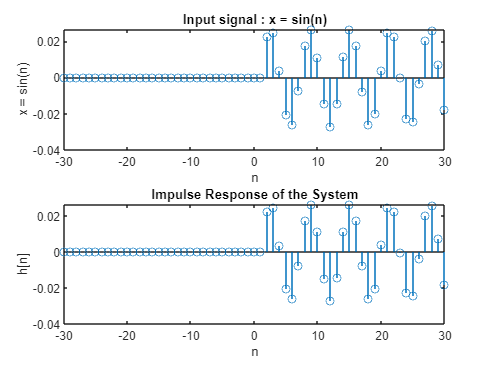

% Given system defined by the equation
% y[n] = 1/3*x[n] - 1/3*x[n-1] + 1/3*x[n-2]

% Define the range of n
n = -30:30;

% Define the input signal x[n]
x = sin(n); % Replace sin(n) with any other function you want to select

% Initialize the impulse response h
h = zeros(size(n));

% Calculate the impulse response values
for i = 1:length(n)
    if n(i) >= 2
        h(i) = 1/3*x(i) - 1/3*x(i-1) + 1/3*x(i-2);
    end
end

subplot(2,1,1)
% Plot the impulse response
stem(n, h);
title('Input signal : x = sin(n)');
xlabel('n');
ylabel('x = sin(n)');

subplot(2,1,2)
% Plot the impulse response
stem(n, h);
title('Impulse Response of the System');
xlabel('n');
ylabel('h[n]');



% Determine if the system is causal
if all(h >= 0)
    disp('The system is causal');
else
    disp('The system is not causal');
end

The system is not causal
